A_1 = 3; F_1 = 200; A_2 = 1.5; F_2 = 750;

%s 2-1
%a & b)
syms F
F_s = double(solve(F_2 == F/2, F))

F_s = 1500

%s 2-2
%a
%Sampling frekvens på 1k ville give en aliaserings frekvens ved 250Hz
F_s = 1e3;
F_alias = F_2-(F_s/2)

F_alias = 250

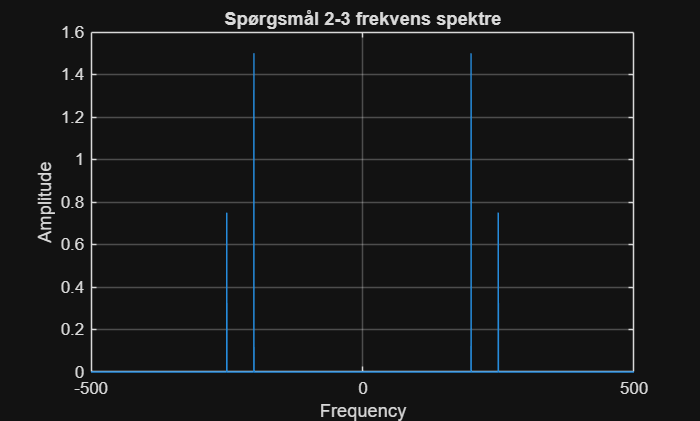

%s 2-3
T_s = 1/F_s; N = 10^5; t = (0:(N-1))*T_s;

x_at = A_1*cos(2*pi*F_1*t)+A_2*cos(2*pi*F_2*t);

X_at = fftshift(fft(x_at));

f_v = -F_s/2:(1/(N*T_s)):(F_s/2)-(1/(N*T_s));

figure();
plot(f_v, abs(X_at)/length(X_at));
ylabel('Amplitude');
xlabel('Frequency');
title('Spørgsmål 2-3 frekvens spektre');
grid on;

%b)
%I plottet ses, at der er en frekvens på 250Hz og 200Hz, hvor den 250Hz er
%aliaseringen af 750Hz

%s 2-4
%a)
F_p = 350; b_p = [1]; a_p = [1 2.6131 3.4142 2.6131 1];

Omega_p = 2*pi*F_p;

%b)
[bt, at] = lp2lp(b_p, a_p, Omega_p);
tf(bt, at)


ans =
 
                        2.339e13
  -----------------------------------------------------
  s^4 + 5747 s^3 + 1.651e07 s^2 + 2.779e10 s + 2.339e13
 
Continuous-time transfer function.


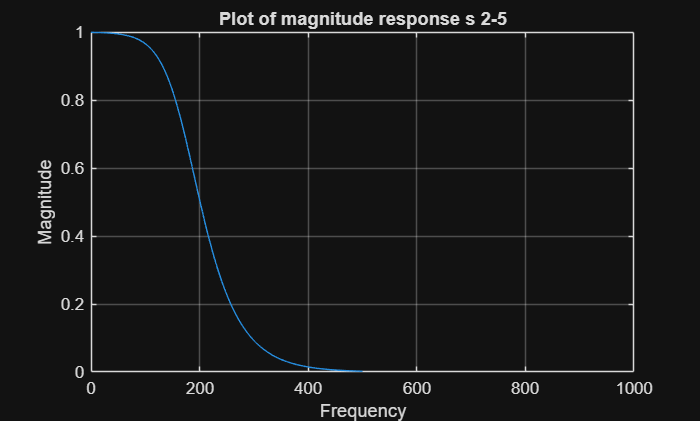

%s 2-5
%a)
%[h, w] = freqs(bt, at, Omega_p);
figure();
plot(f_v, abs(h));
xlim([0 1e3])
ylabel('Magnitude');
xlabel('Frequency');
title('Plot of magnitude response s 2-5');
grid on;

S.4

%a)
f_pL = 45; f_pH = 55.5; f_sL = 48; f_sH = 52.1; A_sdB = 20; A_pdB = 3; F_s = 5e3;

omega_pL = (2*pi*f_pL)/F_s; omega_pH = (2*pi*f_pH)/F_s; omega_sL = (2*pi*f_sL)/F_s; omega_sH = (2*pi*f_sH)/F_s;

Omega_pL = 2*F_s*tan(omega_pL/2)

Omega_pL = 282.8187

Omega_pH = 2*F_s*tan(omega_pH/2)

Omega_pH = 348.8582

Omega_sL = 2*F_s*tan(omega_sL/2)

Omega_sL = 301.6844

Omega_sH = 2*F_s*tan(omega_sH/2)

Omega_sH = 327.4709

%b)
ny = (Omega_pH-Omega_pL)/(Omega_sH-Omega_sL);

epsilon_2 = (10^(0.1*A_pdB)-1);
n = (log10((10^(0.1*A_sdB)-1)/epsilon_2))/(2*log10(ny))

n = 2.4457

%n > 2.4 => n = 3

%c)
b_p = 1; a_p = [1 2 2 1];

tf(b_p, a_p)


ans =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.


%s 4-2
%a)
Omega_0 = sqrt(Omega_pL*Omega_pH)

Omega_0 = 314.1077

W = Omega_pH-Omega_pL

W = 66.0395

[bt, at] = lp2bs(b_p, a_p, Omega_0, W);
tf(bt, at)


ans =
 
  s^6 + 1.946e-13 s^5 + 2.96e05 s^4 + 3.84e-08 s^3 + 2.92e10 s^2 + 0.001894 s + 9.604e14
  --------------------------------------------------------------------------------------
   s^6 + 132.1 s^5 + 3.047e05 s^4 + 2.635e07 s^3 + 3.006e10 s^2 + 1.286e12 s + 9.604e14
 
Continuous-time transfer function.


%s 4-3
%a)
[bd, ad] = bilinear(bt, at, F_s);

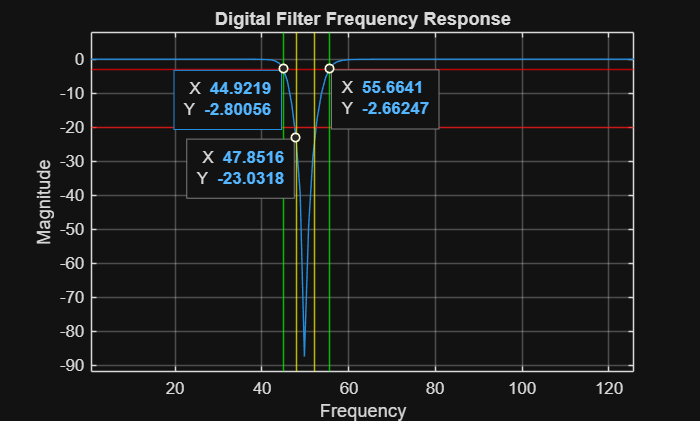


[h, f] = freqz(bd, ad, 512*5, F_s);

figure();
plot(f, 20*log10(abs(h)));
xlim([0 100])
yline([-3 -20], 'r')
xline([f_pL f_pH], 'g')
xline([f_sL f_sH], 'y')
ylabel('Magnitude');
xlabel('Frequency');
title('Digital Filter Frequency Response');
grid on;

xlim([27.7 72.1])
ylim([-43.2 1.2])
 
ax = gca;
chart = ax.Children(7);
datatip(chart,55.66,-2.662);
datatip(chart,47.85,-23.03,"Location","southwest");
datatip(chart,44.92,-2.801,"Location","southwest");
xlim([0.6 125.8])
ylim([-92 8])
 
ax2 = gca;
chart2 = ax2.Children(7);
datatip(chart2,55.66,-2.662);
datatip(chart2,47.85,-23.03,"Location","southwest");
datatip(chart2,44.92,-2.801,"Location","southwest");